**State Space Modeling Tutorial - Part 3, 2D Linear Gaussian Model - Filter and Model Identification**

In the parts 1 and 2 of this tutorial, we examined filter and smoother estimates from state-space models with a single state dimension, in cases where the true modelparmaters were known. In this section, we explore some features of higher dimensional state processes and examine methods to fit the state and observation models when they are unknown.

We will start by generating data from a 2 dimensional state model that has oscillatory dynamics, which is observed through a one-dimensional observation process.

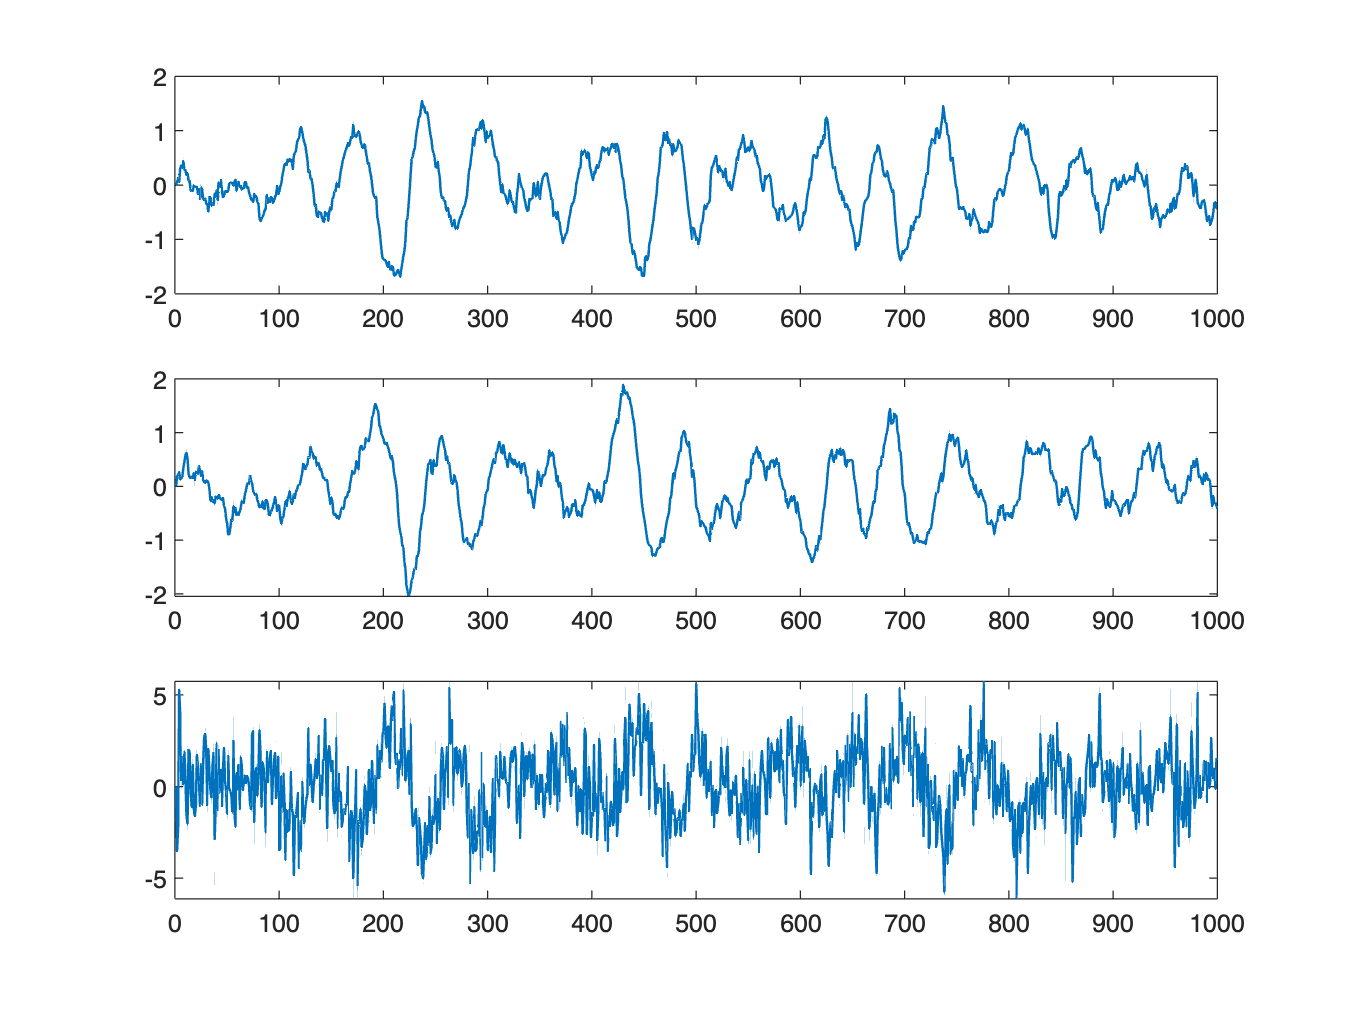

%% 2-D Example
%% Generate data
% State model: x(t) = A*x(t-1) + Sigx * N(0,I)
% Observation model: y(t) = H*x(t) + Sigy * N(0,I)

rng(0); set(0,'DefaultLineMarkerSize',10); set(0,'DefaultLineLineWidth',1);
A = .99*[.995 -.1;.1 .995]; H = [-2 0];
n = size(A,1); m = size(H,1);
Sigx = .1*eye(n); Sigy = 1.5*eye(m);

N = 1000; x = zeros(n,N); y = zeros(m,N); 
for i = 2:N,
    x(:,i) = A*x(:,i-1)+Sigx*normrnd(0,1,n,1);
    y(:,i) = H*x(:,i)+Sigy*normrnd(0,1,m,1);
end;

figure; subplot(311); plot(1:N,x(1,:));
subplot(312); plot(1:N,x(2,:));
subplot(313); plot(1:N,y);

The top two panels show the first and second dimension of the state process, respectively, and the bottom panel shows the observation process, which depends on only the first dimension of the state process. One question is how well the filter will be able to estimate the second dimension of the state process despite the fact that the observations only depend directly on the first dimension.

Numerical integration of the filter becomes more difficult in higher dimensions, but since both the state and observation equations are linear with Gaussian noise terms, the Kalman filter gives a closed-form solution to the filter update equation.

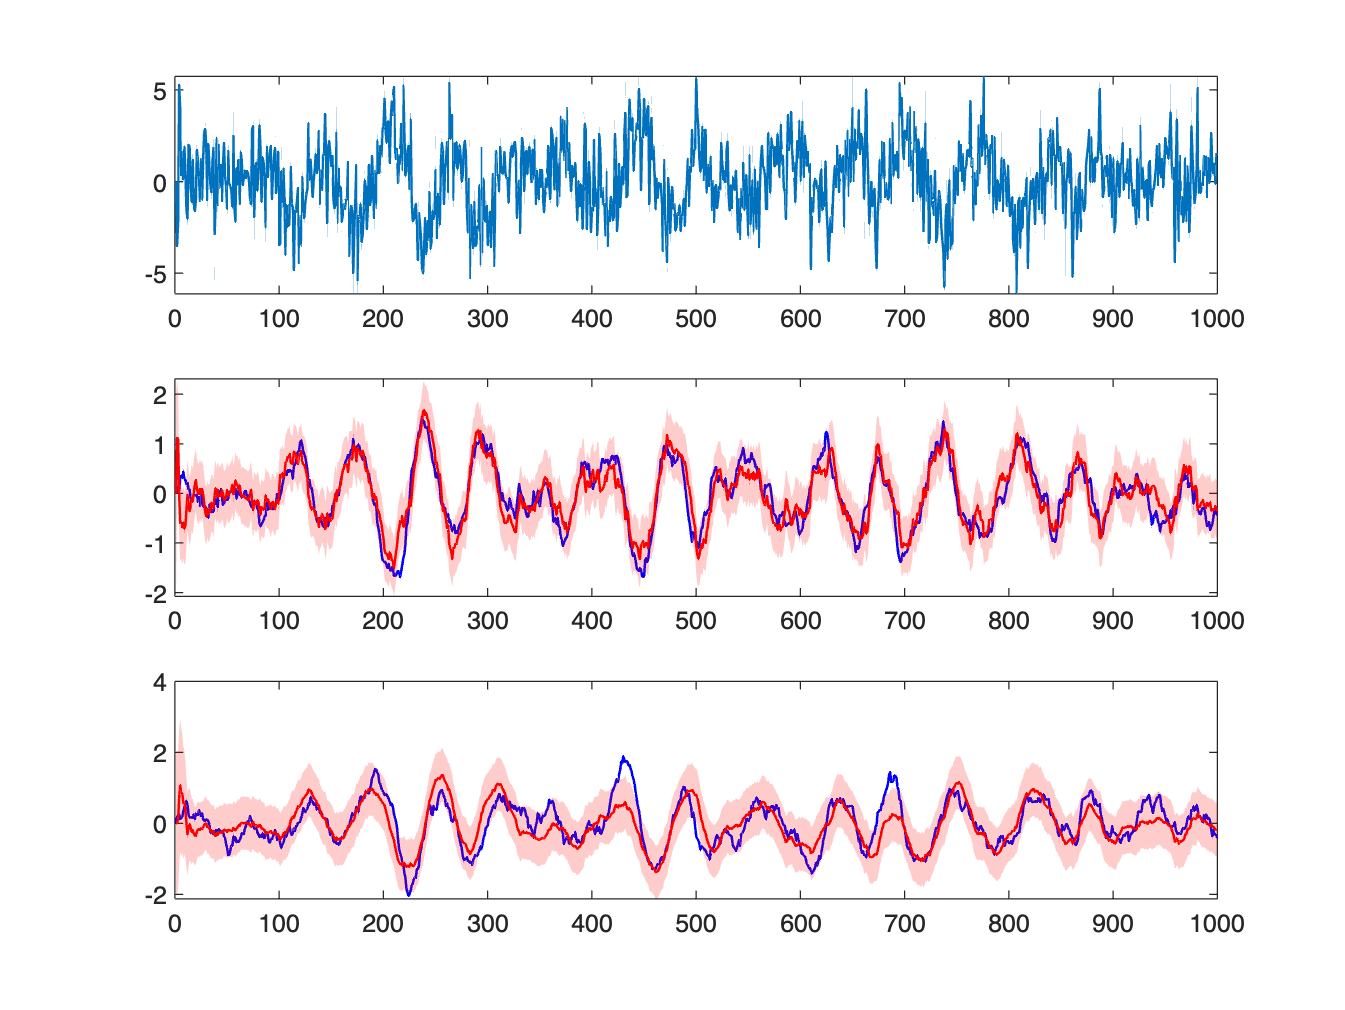


%% Kalman Filter (Textbook)
xK = zeros(n,N); WK = zeros(n,n,N);  WK(:,:,1) = 1*eye(n);  % Allocate memory for xK (filter mean) and WK (filter variance)
for i = 2:N,
    Wos = A*WK(:,:,i-1)*A'+Sigx*Sigx';                      % One-step prediction variance
    S = H*Wos*H'+Sigy*Sigy';                                % Innovation covariance                             
    K = Wos*H'*inv(S);                                      % Kalman gain
    xK(:,i) = A*xK(:,i-1) + K*(y(:,i)-H*A*xK(:,i-1));       % Filter mean     
    WK(:,:,i) = (eye(n)-K*H)*Wos;                           % Filter covariance
    
    V(i) = det(WK(:,:,i));                                  % Save the determinant of the filter covariance at each time
end;

figure; subplot(311); plot(1:N,y);
subplot(312); plot(1:N,x(1,:),'b',1:N,xK(1,:),'r'); U1=xK(1,:)+2*sqrt(squeeze(WK(1,1,:))'); L1=xK(1,:)-2*sqrt(squeeze(WK(1,1,:))'); hold on; fill([1:N N:-1:1], [U1 fliplr(L1)], 'r', 'FaceAlpha',0.2,'EdgeColor','none'); 
subplot(313); plot(1:N,x(2,:),'b',1:N,xK(2,:),'r'); U2=xK(2,:)+2*sqrt(squeeze(WK(2,2,:))'); L2=xK(2,:)-2*sqrt(squeeze(WK(2,2,:))'); hold on; fill([1:N N:-1:1], [U2 fliplr(L2)], 'r', 'FaceAlpha',0.2,'EdgeColor','none'); 

The top panel shows the observations in blue. The second panel shows the true value of the first dimension of the state process in blue, the estimates of the first dimension of the state in red, and 95% confidence bounds on these estimates as a transparent pink region. Even though the observations are quite noisy, the Kalman filter is able to combine information over multiple observations to provide a smooth estimate of x(t). 

The third panel shows the true and estimated values of the second dimension of the state process. Even though the observation only depends directly on the first dimension, the Kalman filter successfully estimates the trajectory of the second dimension of the state process through time.  

Up until now, we have assumed that the state and observation models are known. In some analysis problems, these models might be estimated seperately from training data where the state process is observable. In other cases, it may be neccesary to estimate the state process while simultaneously fitting parameters for the state and observation models. There are multiple approaches to solve this problem, and here we will implement a common approach known as the Expectation-Maximization (EM) algorithm.

The EM algorithm alternates between two steps: an E-step, where the filter and smoother problems are solved to estimate the trajectory of the state process, and an M-step, where the parameter that maximises the expected value of the log likelihood, given the estimated state process is computed.

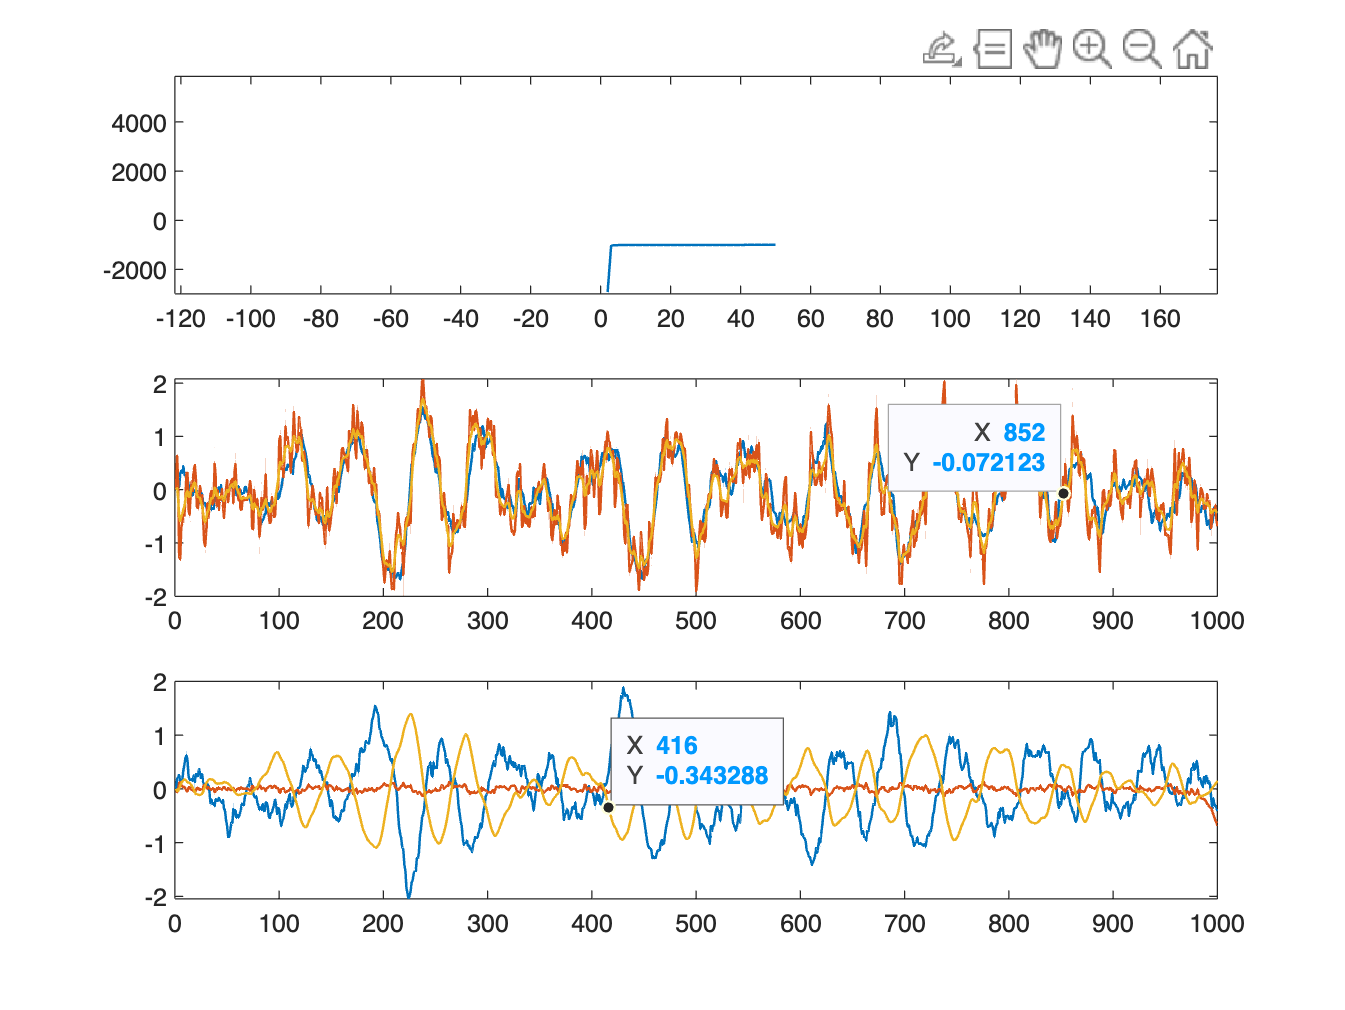


%% EM (on A, Sigx, and Sigy)
numiter = 50; Aem = ones(2,2,numiter); Aem(:,:,1) = [1 .1;.1 1]; Sx2em = ones(2,2,numiter); Sx2em(:,:,1) = .05*eye(2); Sy2em = .2*ones(1,numiter); Q = zeros(1,numiter);
for k = 2:numiter,
    xK = zeros(n,N); WK = zeros(n,n,N); % WK(:,:,1) = eye(n);
    for i = 2:N,    % E-Step Filter 
        Wos = Aem(:,:,k-1)*WK(:,:,i-1)*Aem(:,:,k-1)'+Sx2em(:,:,k-1);
        S = H*Wos*H'+Sy2em(k-1);
        K = Wos*H'*inv(S);
        Innovations = (y(:,i)-H*Aem(:,:,k-1)*xK(:,i-1));
        xK(:,i) = Aem(:,:,k-1)*xK(:,i-1) + K*Innovations;
        WK(:,:,i) = (eye(n)-K*H)*Wos;
        Q(k) = Q(k)-0.5*log(det(S))-0.5*Innovations'*inv(S)*Innovations;
    end;

    xS = zeros(n,N); WS = zeros(n,n,N); Wcov = zeros(n,n,N); xS(:,N) = xK(:,N); WS(:,:,N) = WK(:,:,N); Wcov(:,:,N) = (eye(n)-K*H)*Aem(:,:,k-1)*WK(:,:,N-1);
    for i = N-1:-1:2,   % E-step Smoother
        C = WK(:,:,i)*Aem(:,:,k-1)'*inv(Aem(:,:,k-1)*WK(:,:,i)*Aem(:,:,k-1)'+Sx2em(:,:,k-1));
        xS(:,i) = xK(:,i) + C*(xS(:,i+1)-Aem(:,:,k-1)*xK(:,i));
        WS(:,:,i) = WK(:,:,i) + C*(WS(:,:,i+1)-(Aem(:,:,k-1)*WK(:,:,i)*Aem(:,:,k-1)'+Sx2em(:,:,k-1)))*C';
        C2 = WK(:,:,i-1)*Aem(:,:,k-1)'*inv(Aem(:,:,k-1)*WK(:,:,i-1)*Aem(:,:,k-1)'+Sx2em(:,:,k-1));
        Wcov(:,:,i) = WK(:,:,i)*C2'+ C*(Wcov(:,:,i+1)-Aem(:,:,k-1)*WK(:,:,i))*C2';
    end;
    Aem(:,:,k) = (sum(Wcov,3)+xS(:,2:end)*xS(:,1:end-1)')*inv(sum(WS(:,:,1:end-1),3)+xS(:,1:end-1)*xS(:,1:end-1)');    % M-step on A
    Sx2em(:,:,k) = 1/N*( (sum(WS,3)+xS*xS')-Aem(:,:,k)*(sum(Wcov,3)+xS(:,2:end)*xS(:,1:end-1)')' );    % M-step on Sigx
    Sy2em(k) = 1/N*( y*y' - H*xS*y');   % M-step on Sigy
    xEM(:,:,k) = xS;
end;

figure; subplot(311); plot(2:numiter,Q(2:end));
subplot(312); plot(1:N,x(1,:),1:N,xEM(1,:,2),1:N,xEM(1,:,numiter));
subplot(313); plot(1:N,x(2,:),1:N,xEM(2,:,2),1:N,xEM(2,:,numiter));

The top plot shows the value of the expected log likelihood of the data for the model estimated at each iteration of the E-step. We see this value rise rapidly over the first few iterations. Zoooming in, we find that the expected log likelihood continues to rise gradually with additional iterations as the model parameter estimates improve. 

The middle plot shows the first dimension of the state as a function of time. The real value is in blue, the estimated value at the first iteration of the EM algorithm is shown in red, and the estimated value at the 50th iteration is shown in yellow. The initial estimate in red follows the trajectory of the true state, but is much noisier. Initially, Sigy is underestimated, leading to noise in the observations being attributed to the state. Initially, A is not a rotation matrix, meaning that the information from past observations is not being correctly propagated to the current time step. The estimate after the 50th iteration still follows the trajectory of the true value, but its variability has decreased as the parameter estimates have improved.

The bottom plot shows the second dimension of the state as a function of time. At the first iteration of the EM algorithm the estimated state in red is flat even though the true state in blue oscillates up and down. This is due to the fact that the initial estimate of A does not correctly link the first and second dimensions of the state. Therefore, information about the first state dimension from the observations does not correctly propogate to the estimates of the second state dimension. 

After 50 EM iterations, the estimate of the second state dimension in yellow oscillates up and down, but is strongly anticorrelated with the true state in blue. What is going on? In this case, it turns out that the true state matrix A induced clockwise oscillations in the state process, but EM algorithm converges to a model with equivalent goodness-of-fit to the true model but which oscillates counterclockwise. We can confirm this by outputting the true and estimated A matrix values.

[A Aem(:,:,end)]

